# Panda Map Column

## Grid

grid = OctoGrid(2,2,2,10);

% add column
grid.addBox(1.25,0.9,0,0.2,0.2,2)

## Robot

% robot base transformation
Tbase = [cos(pi/2) -sin(pi/2) 0 0;
     sin(pi/2) cos(pi/2)  0 0;
     0          0           1 0;
     0          0           0 1]*eye(4);
Tbase(1:3,4) = [1,1,0]';

% set joints positions
joints = [0 0 0 0 0 0 0];

[robot_transforms] = GeometricPandaMATLAB(joints, Tbase);

## Show

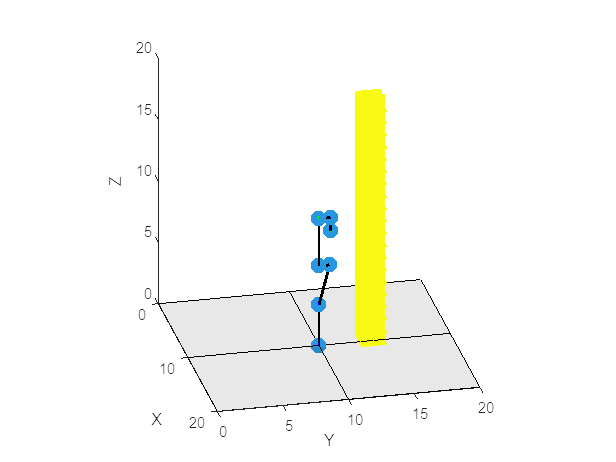

% display
grid.showGridVol3D(grid.grid,'floor',true)
hold on
axis equal
showPanda(robot_transforms,10)
hold off